## **Espace de solutions**

### **Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

% Charger les solutions depuis le fichier
load('solutions.mat');
% Afficher toutes les configurations trouvées en radian
disp('Configurations possibles du robot en rad pour la position désirée :');

Configurations possibles du robot en rad pour la position désirée :


disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé');

    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé


disp(all_solutions);  

    0.9764    5.5874    5.8060    3.7165    3.0895    6.0000    2.0000
    0.6124    0.6045    5.6767    5.0844    5.3113    6.0000    2.0000
    5.9078    1.0828    5.4541    0.5053    2.6187    6.0000    2.0000
    5.4322    0.5127    1.8214    5.0646    1.4335    6.0000    2.0000
    0.5918    5.3879    2.1020    5.4635    4.1521    6.0000    2.0000
    5.5199    1.1124    1.9617    3.6098    1.2808    6.0000    2.0000
    5.1608    1.2936    0.1197    0.3644    1.6395    6.0000    2.0000
    1.1962    6.0318    4.7245    5.3609    1.9799    6.0000    2.0000
    5.5557    0.8916    1.2022    4.3731    2.4043    6.0000    2.0000
    5.7350    0.8784    1.2426    3.5608    2.3937    6.0000    2.0000
    5.8403    0.3768    1.6249    4.2913    2.3295    6.0000    2.0000
    1.2049    4.3358    0.7590    0.1542    1.8649    6.0000    2.0000
    0.1438    5.5182    1.0295    0.4203    1.6748    6.0000    2.0000
    1.7669    4.8737    4.6757    0.8500    1.3845    6.0000    2.0000
    5.

    

% Convertion des angles de radians en degrés et afficher les résultats
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
% % Afficher toutes les configurations trouvées en degrrs
% disp('Configurations possibles du robot en degres pour la position désirée :');
% disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')
% disp([all_solutions_deg, all_solutions(:, 6:7)]);
 

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;
% Afficher toutes les configurations trouvées en degrrs
disp('Configurations possibles du robot en degres dans intervalle -180 180 :');

Configurations possibles du robot en degres dans intervalle -180 180 :


disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')

    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé


disp([all_solutions_deg, all_solutions(:, 6:7)]);

   55.9460  -39.8638  -27.3383 -147.0587  177.0181    6.0000    2.0000
   35.0853   34.6338  -34.7479  -68.6832  -55.6870    6.0000    2.0000
  -21.5085   62.0421  -47.5029   28.9508  150.0384    6.0000    2.0000
  -48.7551   29.3762  104.3598  -69.8190   82.1329    6.0000    2.0000
   33.9078  -51.2938  120.4359  -46.9651 -122.1042    6.0000    2.0000
  -43.7358   63.7371  112.3993 -153.1744   73.3821    6.0000    2.0000
  -64.3051   74.1191    6.8567   20.8786   93.9359    6.0000    2.0000
   68.5357  -14.4046  -89.3051  -52.8432  113.4387    6.0000    2.0000
  -41.6825   51.0821   68.8786 -109.4415  137.7556    6.0000    2.0000
  -31.4070   50.3311   71.1978 -155.9798  137.1517    6.0000    2.0000
  -25.3780   21.5899   93.0987 -114.1251  133.4730    6.0000    2.0000
   69.0384 -111.5795   43.4886    8.8354  106.8488    6.0000    2.0000
    8.2376  -43.8310   58.9849   24.0837   95.9573    6.0000    2.0000
  101.2332  -80.7560  -92.1034   48.7014   79.3275    6.0000    2.0000
  -26.

### **Variation de theta pour chaque solution**

% Définir le nombre total de solutions
num_solutions = size(all_solutions, 1);
% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques
% Définir les positions des subplots
position = reshape(1:num_rows*num_cols, num_cols, num_rows).';

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
all_solutions_deg = rad2deg(all_solutions(:, 1:5));
all_solutions_deg = mod(all_solutions_deg + 180, 360) - 180;

% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k','HandleVisibility', 'off');
    end

    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation déjà ajustés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_1 = interp1(x_data, y_data, finer_x, 'spline');
    interpolated_2 = interp1(x_data, y_data, finer_x, 'linear');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_1, 'r-', 'LineWidth', 1, 'DisplayName', 'Interpolation Spline');
    plot(finer_x, interpolated_2, 'k-', 'LineWidth', 1, 'DisplayName', 'Interpolation Lineaire');

    % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
    max_theta = max(all_solutions_deg(:, joint));
    min_theta = min(all_solutions_deg(:, joint));
    
    % Ajouter du texte à la position souhaitée
    text(-1, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
    text(-1, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
    disp(['Pour theta', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);

    % Tracer une droite représentant la valeur maximale de theta pour cet angle d'articulation
    plot([1, num_solutions], [max_theta, max_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Max Theta', num2str(joint)]);

    % Tracer une droite représentant la valeur minimale de theta pour cet angle d'articulation
    plot([1, num_solutions], [min_theta, min_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Min Theta', num2str(joint)]);
      
end

Pour theta1, Theta max : 101.2332, Theta min : -64.3051
Pour theta2, Theta max : 88.8819, Theta min : -111.5795
Pour theta3, Theta max : 125.0754, Theta min : -92.1034
Pour theta4, Theta max : 128.1393, Theta min : -160.8166
Pour theta5, Theta max : 177.0181, Theta min : -179.0734


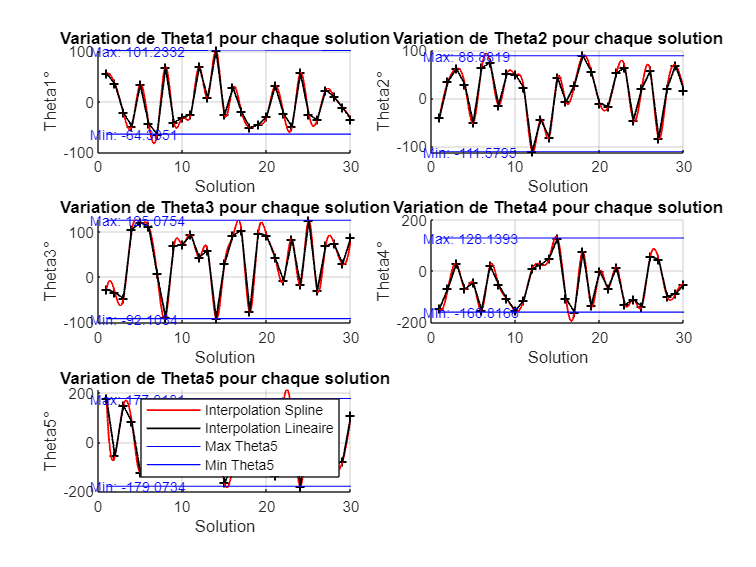


% Légende
legend('show');

#### Courbe des angles pour chaque solution - interpolation

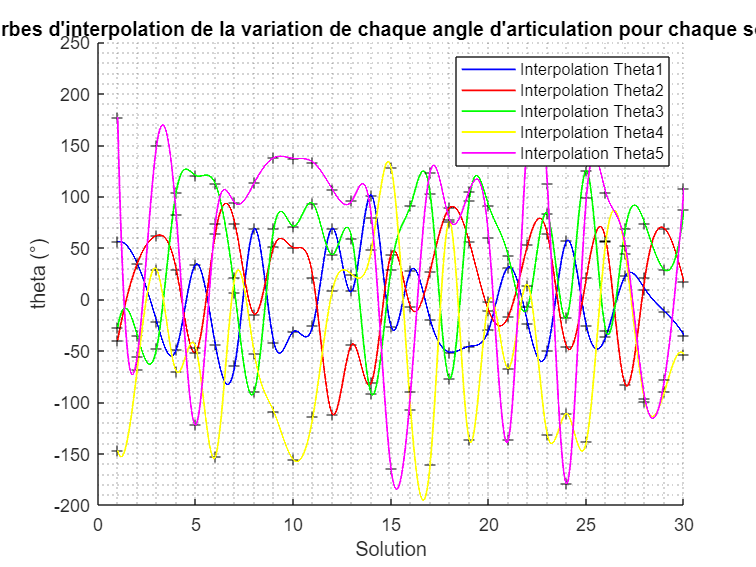

%Courbe de chaque angles 
% Créer une nouvelle figure
figure;

% Titre et étiquettes des axes
title('Courbes d''interpolation de la variation de chaque angle d''articulation pour chaque solution');
xlabel('Solution');
ylabel('theta (°)');
grid minor;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Tracer les valeurs des angles d'articulation pour chaque solution en convertissant les radians en degrés
    for i = 1:num_solutions
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = all_solutions_deg(i, joint);
        % Tracer l'angle d'articulation pour cette solution avec un marqueur plein
        plot(i, theta_deg, '+', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k', 'HandleVisibility', 'off');

    end
    
    % Calculer une interpolation linéaire des données
    x_data = 1:num_solutions; % Les données x sont simplement les indices des solutions
    y_data = all_solutions_deg(:, joint); % Les données y sont les angles d'articulation convertis en degrés
    
    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, num_solutions, 10000); % 1000 points entre le premier et le dernier index
    
    % Calculer les valeurs interpolées
    interpolated_y = interp1(x_data, y_data, finer_x, 'spline');
    
    % Couleurs pour chaque angle d'articulation
    colors = ['b', 'r', 'g', 'y', 'm'];
    
    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_y, '-', 'DisplayName', ['Interpolation Theta', num2str(joint)], 'LineWidth', 1, 'Color', colors(joint));
end
        
legend("show")  

#### Positions des articulations pour chaque solution

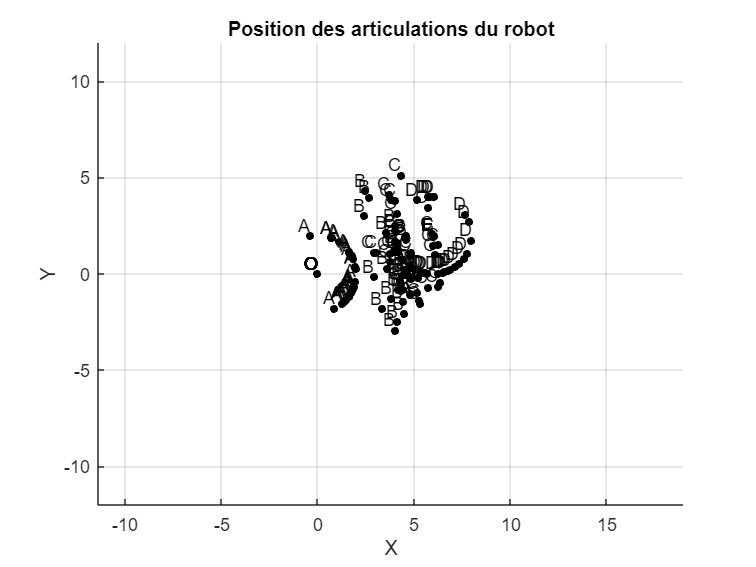

% Créer un graphique distinct pour les articulations du robot
figure;


hold on; % Garder le graphique actif pour ajouter les données de chaque solution


% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

#### Graphique separe pour chaque articulation

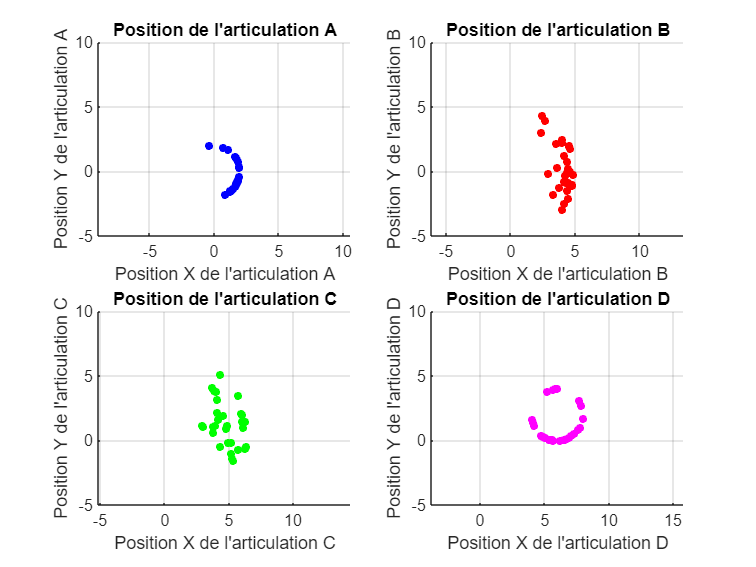

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire l'angle d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(all_solutions, 1), 2);
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;

## Filtrage des solutions

### 1. Selon les butées des angles d'articulation

disp('SOLUTIONS FILTREES')

SOLUTIONS FILTREES


% Spécifier les intervalles d'angle souhaités
intervalles = [-90, 90; -90, 90; -90, 90; -90, 90; -90, 90]; % Par exemple, [-90, 90] pour tous les angles

% Tri des solutions qui respectant les butees
trisolution = all(all_solutions_deg >= intervalles(:, 1)' & all_solutions_deg <= intervalles(:, 2)', 2);
% Tableau pour stocker les résultats finaux
resultats_finaux = [];
% Afficher toutes les configurations trouvées
disp('Configurations possibles du robot dans l''intervalle [-180, 180] respectant les intervalles d''angle spécifiés:');

Configurations possibles du robot dans l'intervalle [-180, 180] respectant les intervalles d'angle spécifiés:


disp('    Theta1°    Theta2°     Theta3°     Theta4°    Theta5° ');

    Theta1°    Theta2°     Theta3°     Theta4°    Theta5° 


for i = 1:size(all_solutions_deg, 1)
    if trisolution(i)
        disp([sprintf('%9.2f   %9.2f   %9.2f   %9.2f   %9.2f', all_solutions_deg(i, :))]);
        % Ajouter la solution filtrée au tableau des résultats finaux
        resultats_finaux = [resultats_finaux; all_solutions_deg(i, :), all_solutions(i, 6:7)];
   
    else
        disp([sprintf('%9.2f   %9.2f   %9.2f   %9.2f   %9.2f', all_solutions_deg(i, :))]);
    end
end

    55.95      -39.86      -27.34     -147.06      177.02


    35.09       34.63      -34.75      -68.68      -55.69


   -21.51       62.04      -47.50       28.95      150.04
   -48.76       29.38      104.36      -69.82       82.13
    33.91      -51.29      120.44      -46.97     -122.10
   -43.74       63.74      112.40     -153.17       73.38
   -64.31       74.12        6.86       20.88       93.94
    68.54      -14.40      -89.31      -52.84      113.44
   -41.68       51.08       68.88     -109.44      137.76
   -31.41       50.33       71.20     -155.98      137.15
   -25.38       21.59       93.10     -114.13      133.47
    69.04     -111.58       43.49        8.84      106.85
     8.24      -43.83       58.98       24.08       95.96
   101.23      -80.76      -92.10       48.70       79.33
   -26.16       43.66       29.40      128.14     -165.08
    27.68       -7.27       91.26     -107.09      -89.93
   -19.49       27.38      102.96     -160.82      123.45


   -51.33       88.88      -77.07       75.32       77.56


   -45.71       56.38       96.13     -136.07      105.12
   -29.49      -11.09       91.20       -2.49       60.02
    31.28      -17.02       42.41      -67.23     -136.68
   -23.25       53.46       -7.28       13.77      163.62
   -49.90       63.77       83.17     -131.60      113.10
    56.86      -46.32      -17.38     -111.39     -179.07
   -25.39       21.08      125.08     -138.53       98.55
   -36.28       57.21      -30.37       56.60      103.73


    22.86      -83.09       68.77       44.45       51.89


     9.92       20.97       73.55      -99.31      -96.22


   -11.68       68.89       28.78      -89.76      -78.15


   -35.03       17.04       87.32      -53.48      108.23




disp('RESULTATS FINAUX RESPECTANT LES CONDITIONS DE BUTEES')

RESULTATS FINAUX RESPECTANT LES CONDITIONS DE BUTEES


disp('    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé');

    Theta1°   Theta2°   Theta3°   Theta4°   Theta5°   X_calculé   Y_calculé


disp(resultats_finaux);

   35.0853   34.6338  -34.7479  -68.6832  -55.6870    6.0000    2.0000
  -51.3323   88.8819  -77.0721   75.3220   77.5592    6.0000    2.0000
   22.8609  -83.0922   68.7734   44.4550   51.8929    6.0000    2.0000
  -11.6817   68.8863   28.7809  -89.7638  -78.1498    6.0000    2.0000



### Affichage des solutions filtres

- Position des articulations du robot pour les solutions respectant les butees 

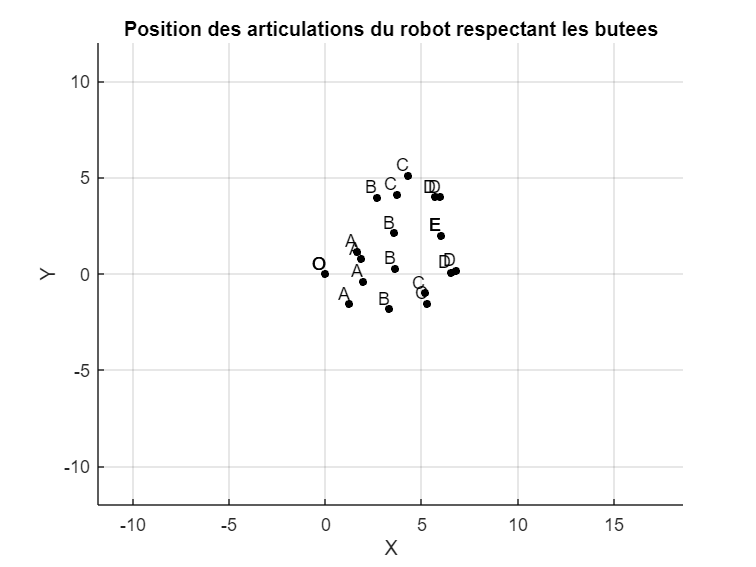

% Position darticulations du robot
figure;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution
% Visualisation des configurations du robot pour les solutions filtrées uniquement
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    theta3 = resultats_finaux(i, 3);
    theta4 = resultats_finaux(i, 4);
    theta5 = resultats_finaux(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    B = A + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cosd(theta1+theta2+theta3+theta4+theta5), a5*sind(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
grid on;

% Calc2. uler les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot respectant les butees');
xlabel('X');
ylabel('Y');

2. Position de chaque articulation pour les solutions filtrees

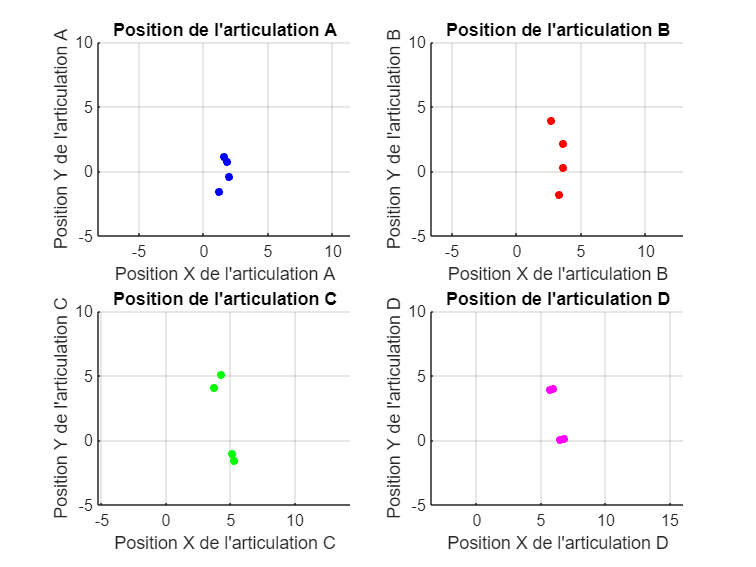

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution finale
A_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution finale
B_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = [a1*cosd(theta1), a1*sind(theta1)] + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y


% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution finale
C_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    theta3 = resultats_finaux(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = [a1*cosd(theta1), a1*sind(theta1)] + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)] + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution finale
D_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    theta3 = resultats_finaux(i, 3);
    theta4 = resultats_finaux(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = [a1*cosd(theta1), a1*sind(theta1)] + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)] + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)] + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y


% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;



% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution
    for i = 1:size(resultats_finaux, 1)
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = resultats_finaux(i, joint);

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k','HandleVisibility', 'off');
    end

    % Calculer une interpolation linéaire des données
    x_data = 1:size(resultats_finaux, 1); % Les données x sont simplement les indices des solutions
    y_data = resultats_finaux(:, joint); % Les données y sont les angles d'articulation déjà ajustés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, size(resultats_finaux, 1), 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_1 = interp1(x_data, y_data, finer_x, 'spline');
    interpolated_2 = interp1(x_data, y_data, finer_x, 'linear');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_1, 'r-', 'LineWidth', 1, 'DisplayName', 'Interpolation Spline');
    plot(finer_x, interpolated_2, 'k-', 'LineWidth', 1, 'DisplayName', 'Interpolation Lineaire');

    % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
    max_theta = max(resultats_finaux(:, joint));
    min_theta = min(resultats_finaux(:, joint));
    
    % Ajouter du texte à la position souhaitée
    text(-1, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
    text(-1, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
    disp(['Pour theta', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);

    % Tracer une droite représentant la valeur maximale de theta pour cet angle d'articulation
    plot([1, size(resultats_finaux, 1)], [max_theta, max_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Max Theta', num2str(joint)]);
    
    % Tracer une droite représentant la valeur minimale de theta pour cet angle d'articulation
    plot([1, size(resultats_finaux, 1)], [min_theta, min_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Min Theta', num2str(joint)]);

end

Pour theta1, Theta max : 35.0853, Theta min : -51.3323
Pour theta2, Theta max : 88.8819, Theta min : -83.0922
Pour theta3, Theta max : 68.7734, Theta min : -77.0721
Pour theta4, Theta max : 75.322, Theta min : -89.7638
Pour theta5, Theta max : 77.5592, Theta min : -78.1498


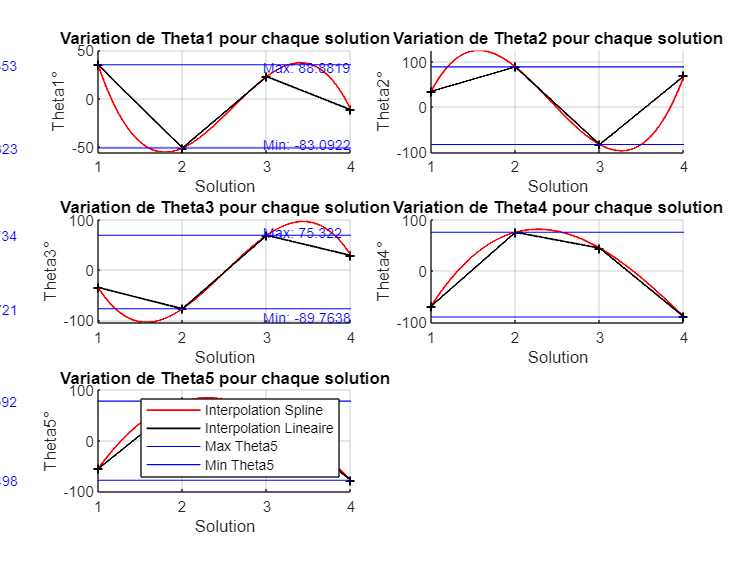


% Légende
legend('show');